**AnalysisPipelineBuilder App**

Purpose

AnalysisPipelineBuilder is an App that allows you to construct pipelines to analyze your data and store and export the results. Please read the "Pipelines" section of the Overview doc so that you are familiar with the concept before proceeding through this section. 

Opening the App

To open the app call it from the command line:

AnalysisPipelineBuilder;

 1:  vfsmdatajoint01.fsm.northwestern.edu via TCP/IP   Server version 8.0.20 (encrypted)


new_data_only = logical
   1


loading
Param set first500ms_pre_stim_post loaded.
loading
Param set first500ms_pre_stim_post loaded.


Before you can get into the main window, this will open up the PipelineSelector window that looks like this.

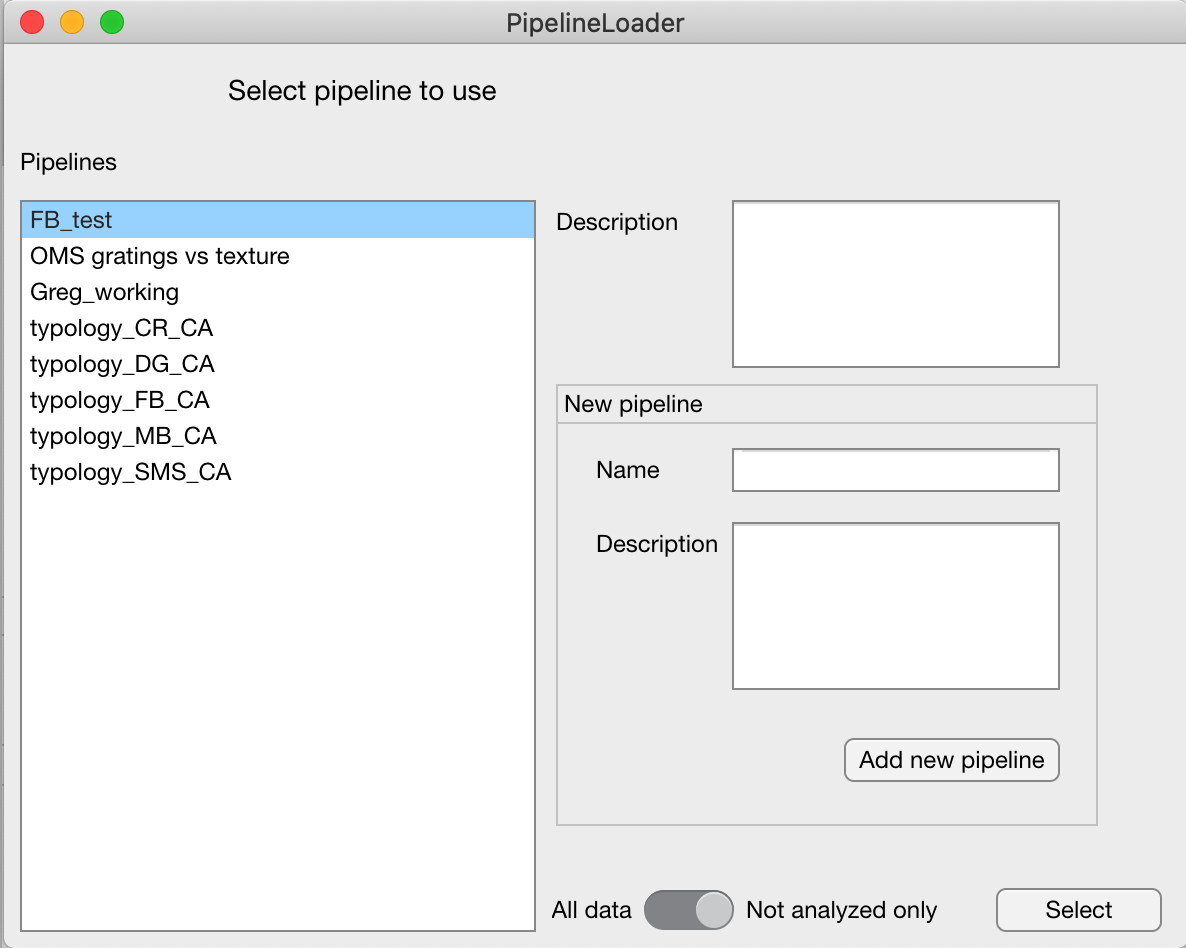

In this window, you can select a pipelline to load or you can add a new one first and then select it. 

Add a new pipeline so you an start playing around with the features of the App. To do so, type a name and description in the "New pipeline" panel and then press "Add new pipeline". Then your new pipeline should appear in the list on the left. For playing around with different data, I suggest keeping a blank "working" pipeline named something like "Greg_working". 

Once you select your pipeline from the list, you can decide to open it with "All data" or "Not analyzed data". This is just a view setting that can be changed inside the main App. For your new blank pipeline this makes no difference, but eventually you may have a large input query, and it could be faster to open the App in a view that only shows the new "unanalyzed" data. Press "Select" to dismiss the PipelineLoader window and reveal the main App window.

Parts of the pipeline / panels of the App

The main window looks like this. 

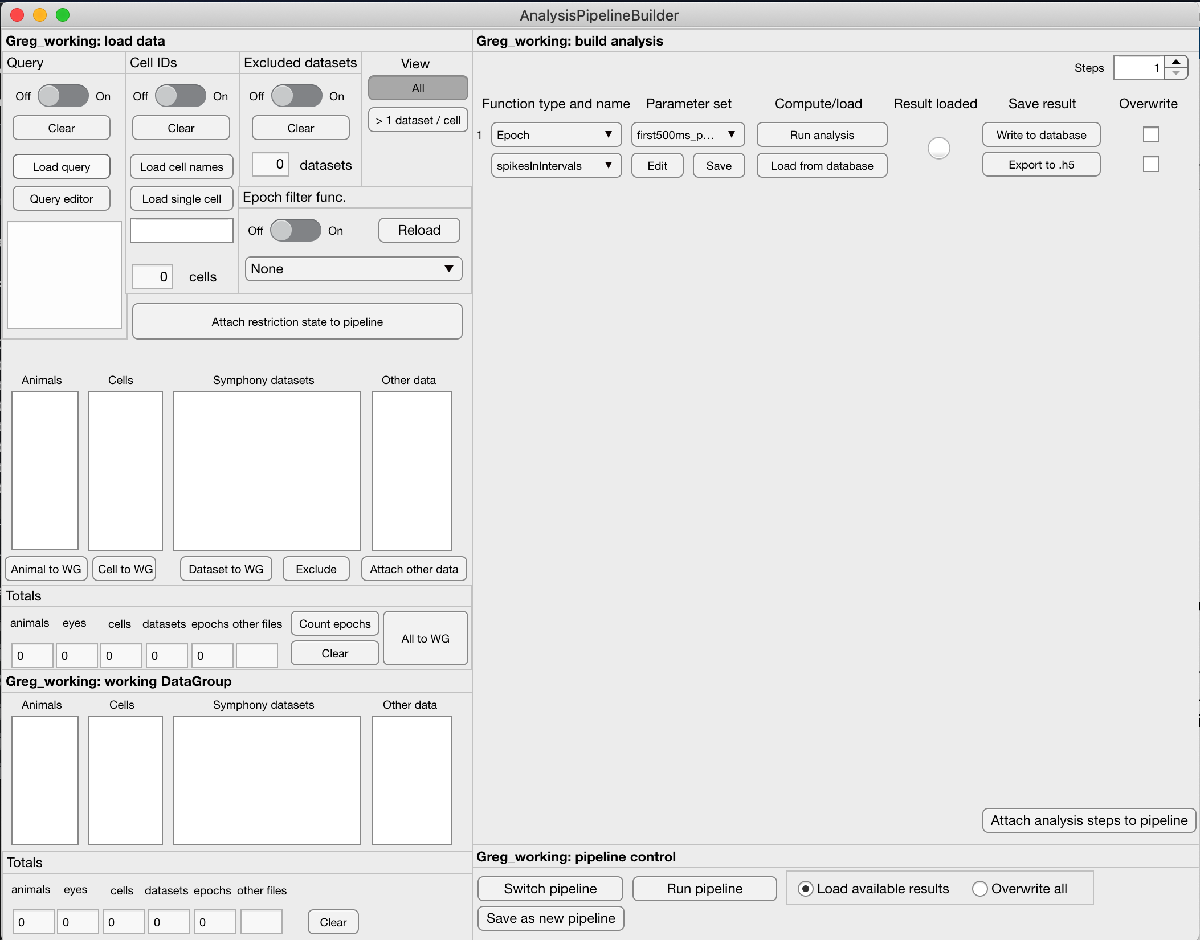

I realize there is a lot going on here! First, note different "panels" in the app. The left side has the "load data" and "working DataGroup" panels and the right side has the "build analysis" and "pipeline control" panels. These first 3 panels are each associated with a different part of the pipeline and the control panel is for running the whole thing or switching to a new pipeline. I will review the parts of the pipeline and tell you where each is stored in the database. Then I will show you how they are manipulated in the app. 

Input query

The input query for your pipeline determines the group of Datasets that that provide the input to your analysis. 

The pipeline name, description text, and the owner (user who created it) are stored in 

sl.Pipeline

If you run that command, you should see some of the stored pipelines. 

The actual input query will be stored in 

sl_mutable.PipelineQuery

When you press the big button labeled "Attach restriction state to pipeline" all the settings in the "load data" panel are stored here, overwriting anything that was there before. When you load a pipeline, it will read in the settings from this table if there is an entry for your pipeline. Thus, sl_mutable.PipelineQuery can only have either zero or one entries for each pipeline. 